%% Векторный расчет нагрузок для всех 10 жилых домов микрорайона
% Формируем векторы исходных данных (каждая строка — это данные для дома от 1 до 10) 

Houses = (1:10)'; % Номера домов от 1 до 10
n_kv = [80; 80; 80; 120; 120; 120; 80; 80; 120; 224]; % Количество квартир 
P_ud_kv = [0.95; 0.95; 0.95; 0.84; 0.84; 0.84; 0.95; 0.95; 0.84; 1.35]; % Удельная мощность, кВт 
tg_phi_kv = [0.29; 0.29; 0.29; 0.29; 0.29; 0.29; 0.29; 0.29; 0.29; 0.20]; % Тангенс фи (0.2 для 14-этажки с электроплитами) 

n_lift = [4; 4; 4; 6; 6; 6; 4; 4; 6; 8]; % Количество лифтов 
P_lift_nom = [4.5; 4.5; 4.5; 4.5; 4.5; 4.5; 4.5; 4.5; 4.5; 7.0]; % Мощность 1 лифта, кВт 
k_s_lift = [0.65; 0.65; 0.65; 0.50; 0.50; 0.50; 0.65; 0.65; 0.50; 0.675]; % Коэф. спроса лифтов 

K_o = 0.9;          % Коэф. одновременности (квартиры + сила) [cite: 90, 91]
tg_phi_lift = 1.17; % Тангенс фи для лифтов [cite: 95]

%% Выполнение векторных расчетов
% Обрати внимание на оператор ".*" - это поэлементное умножение матриц.
% MATLAB возьмет первый элемент первого вектора, умножит на первый элемент второго и т.д.

P_kv = P_ud_kv .* n_kv;               % Активная мощность квартир, кВт [cite: 82]
Q_kv = P_kv .* tg_phi_kv;             % Реактивная мощность квартир, кВар [cite: 111]

P_lift = n_lift .* P_lift_nom .* k_s_lift; % Активная мощность лифтов, кВт [cite: 92]
Q_lift = P_lift .* tg_phi_lift;            % Реактивная мощность лифтов, кВар [cite: 113]

P_santex = 0.05 .* n_kv;              % Активная мощность сантехники, кВт [cite: 95]
Q_santex = P_santex .* 0.75;          % Реактивная мощность сантехники, кВар [cite: 114]

% Суммарная силовая нагрузка
P_c = P_lift + P_santex;
Q_c = Q_lift + Q_santex;

% Расчетная нагрузка на вводе в здания
P_zd = P_kv + K_o .* P_c;             % Полная активная мощность здания, кВт [cite: 90]
Q_zd = Q_kv + K_o .* Q_c;             % Полная реактивная мощность здания, кВар [cite: 115]

S_zd = sqrt(P_zd.^2 + Q_zd.^2);       % Полная мощность здания, кВА (обрати внимание на .^ для возведения вектора в степень) [cite: 132]

%% Создание красивой сводной таблицы для вывода (как в твоей записке!)
% Функция table() идеально подходит для генерации отчетов в Live Editor
ResultTable = table(Houses, P_zd, Q_zd, S_zd, ...
    'VariableNames', {'N_doma', 'P_aktivnaya_kVT', 'Q_reaktivnaya_kVAR', 'S_polnaya_kVA'})

ResultTable = 10×4 table
    N_doma    P_aktivnaya_kVT    Q_reaktivnaya_kVAR    S_polnaya_kVA
    ______    _______________    __________________    _____________

       1           90.13                37.06             97.452    
       2           90.13                37.06             97.452    
       3           90.13                37.06             97.452    
       4          118.35               47.497             127.53    
       5          118.35               47.497             127.53    
       6          118.35               47.497             127.53    
       7           90.13                37.06             97.452    
       8           90.13                37.06             97.452    
       9          118.35               47.497             127.53    
      10           346.5               107.84             362.89    



% Суммарная нагрузка по всем жилым домам (для сверки с итогами)
Sum_P = sum(P_zd);
Sum_Q = sum(Q_zd);
Sum_S = sum(S_zd);
fprintf('\n--- ИТОГО ПО ВСЕМ 10 ДОМАМ ---\n');


--- ИТОГО ПО ВСЕМ 10 ДОМАМ ---


fprintf('Суммарная активная мощность: %.2f кВт\n', Sum_P);

Суммарная активная мощность: 1270.55 кВт


fprintf('Суммарная реактивная мощность: %.2f кВар\n', Sum_Q);

Суммарная реактивная мощность: 483.13 кВар


fprintf('Суммарная полная мощность: %.2f кВA\n', Sum_S);

Суммарная полная мощность: 1360.26 кВA


%% Глава 3.2. Расчет центров электрических нагрузок и визуализация (Карта микрорайона)
% Данные для ТП1 (Дома 1-5 и Универмаг) из Таблицы 3.2
S_TP1 = [97.2; 97.2; 97.2; 127.6; 127.6; 75.0]; % Мощности, кВА
X_TP1 = [515; 600; 557; 640; 480; 572];         % Координаты X, м
Y_TP1 = [210; 210; 273; 273; 275; 366];         % Координаты Y, м

% Данные для ТП2 (Дома 6-10, Магазин, Муз. школа) из Таблицы 3.2
S_TP2 = [127.6; 97.2; 97.2; 127.6; 362.7; 30.0; 25.0]; 
X_TP2 = [423; 330; 243; 218; 290; 197; 442];
Y_TP2 = [230; 243; 288; 238; 383; 344; 284];

%% Расчет координат центров нагрузок по формулам
% Используем векторизацию: перемножаем векторы поэлементно (.*) и суммируем
X_c1 = sum(S_TP1 .* X_TP1) / sum(S_TP1);
Y_c1 = sum(S_TP1 .* Y_TP1) / sum(S_TP1);

X_c2 = sum(S_TP2 .* X_TP2) / sum(S_TP2);
Y_c2 = sum(S_TP2 .* Y_TP2) / sum(S_TP2);

% Вывод результатов в консоль
fprintf('\n--- Координаты центров нагрузок ---\n');


--- Координаты центров нагрузок ---


fprintf('ТП1: X = %.1f м, Y = %.1f м\n', X_c1, Y_c1);

ТП1: X = 560.2 м, Y = 264.9 м


fprintf('ТП2: X = %.1f м, Y = %.1f м\n', X_c2, Y_c2);

ТП2: X = 299.4 м, Y = 308.6 м


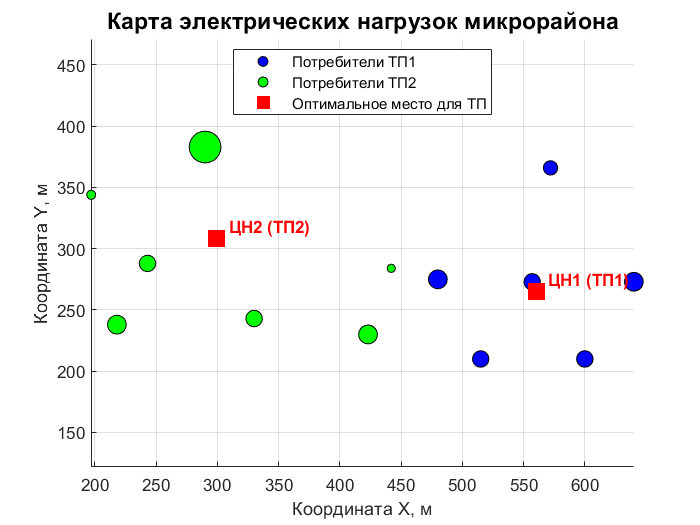


%% Построение интерактивной карты микрорайона (Ситуационный план)
figure('Name', 'Ситуационный план микрорайона', 'Color', 'w');
hold on; grid on;

% Функция scatter строит точки, где размер круга зависит от мощности (S)
% Круги для ТП1 - синие, для ТП2 - зеленые
scatter(X_TP1, Y_TP1, S_TP1, 'b', 'filled', 'MarkerEdgeColor', 'k');
scatter(X_TP2, Y_TP2, S_TP2, 'g', 'filled', 'MarkerEdgeColor', 'k');

% Рисуем сами подстанции (центры масс) в виде крупных красных квадратов
plot(X_c1, Y_c1, 'rs', 'MarkerSize', 12, 'MarkerFaceColor', 'r');
plot(X_c2, Y_c2, 'rs', 'MarkerSize', 12, 'MarkerFaceColor', 'r');

% Добавляем подписи для ТП
text(X_c1 + 10, Y_c1 + 10, 'ЦН1 (ТП1)', 'FontSize', 10, 'FontWeight', 'bold', 'Color', 'r');
text(X_c2 + 10, Y_c2 + 10, 'ЦН2 (ТП2)', 'FontSize', 10, 'FontWeight', 'bold', 'Color', 'r');

% Оформление графика
title('Карта электрических нагрузок микрорайона', 'FontSize', 14);
xlabel('Координата X, м');
ylabel('Координата Y, м');
legend('Потребители ТП1', 'Потребители ТП2', 'Оптимальное место для ТП', 'Location', 'best');
axis equal; % Чтобы масштаб по осям X и Y был одинаковым (не искажал расстояния)
hold off;

%% Глава 4. Расчет сети 6 кВ (Выбор кабелей и проверка потери напряжения)
% Ввод исходных данных из Таблицы 4.3 и расчетов главы 4.5
Line_Names = ["ЦРП-ТП1"; "ТП1-ТП2"; "ЦРП-ТП2"; "ТП2-ТП1"];
L_km = [0.198; 0.377; 0.508; 0.377];        % Длина линий, км
S_p = [666.0; 884.7; 666.0; 595.4];         % Расчетная полная мощность, кВА
P_kw = [617.67; 808.00; 617.67; 550.0];     % Активная мощность, кВт (из формул 4.4)
Q_kvar = [251.91; 306.90; 251.91; 225.0];   % Реактивная мощность, кВар

U_nom = 6.0;           % Номинальное напряжение сети, кВ
J_ek = 1.7;            % Экономическая плотность тока, А/мм^2 (из текста)
r_0 = 0.3;             % Активное сопротивление, Ом/км
x_0 = 0.2;             % Реактивное сопротивление, Ом/км

% Стандартный ряд сечений кабелей (мм^2)
Standard_Sections = [16, 25, 35, 50, 70, 95, 120, 150, 185, 240];

%% 1. Расчет токов и выбор сечения по экономической плотности
% Ток нормального режима (I_p = S_p / (sqrt(3) * U_nom))
I_p = S_p ./ (sqrt(3) * U_nom);

% Ток послеаварийного режима (при выходе из строя одного луча)
I_par = I_p .* 2; 

% Расчетное экономическое сечение
F_ek = I_p ./ J_ek;

% Автоматический выбор ближайшего большего стандартного сечения
F_st = zeros(4, 1); % Пустой вектор для результатов
for i = 1:4
    % Находим первое стандартное сечение, которое больше или равно расчетному
    idx = find(Standard_Sections >= F_ek(i), 1);
    F_st(i) = Standard_Sections(idx);
end

%% 2. Проверка потери напряжения (в нормальном режиме)
% Формула: dU = (P*r0 + Q*x0) / U_nom * L
dU_V = (P_kw .* r_0 + Q_kvar .* x_0) ./ U_nom .* L_km;
dU_percent = (dU_V ./ (U_nom * 1000)) .* 100;

%% 3. Вывод результатов в сводную таблицу
% Формируем красивую таблицу для Live Editor
Table_6kV = table(Line_Names, L_km, S_p, I_p, I_par, F_ek, F_st, dU_percent, ...
    'VariableNames', {'Линия', 'Длина_км', 'S_расч_кВА', 'I_норм_А', 'I_авар_А', ...
                      'F_экон_мм2', 'F_стандарт_мм2', 'Потеря_напряжения_dU_%'})

Table_6kV = 4×8 table
      Линия      Длина_км    S_расч_кВА    I_норм_А    I_авар_А    F_экон_мм2    F_стандарт_мм2    Потеря_напряжения_dU_%
    _________    ________    __________    ________    ________    __________    ______________    ______________________

    "ЦРП-ТП1"     0.198          666        64.086      128.17       37.698            50                 0.12963        
    "ТП1-ТП2"     0.377        884.7         85.13      170.26       50.077            70                 0.31813        
    "ЦРП-ТП2"     0.508          666        64.086      128.17       37.698            50                 0.33257        
    "ТП2-ТП1"     0.377        595.4        57.292      114.58       33.701            35      


% Проверка условия dU < 5%
if all(dU_percent < 5)
    fprintf('✅ Проверка пройдена: потери напряжения на всех участках меньше 5%%.\n');
else
    fprintf('❌ ВНИМАНИЕ: Есть участки с потерей напряжения более 5%%!\n');
end

✅ Проверка пройдена: потери напряжения на всех участках меньше 5%.


%% Глава 5. Расчет сети 0,4 кВ (Выбор кабелей и проверка потери напряжения)
% Исходные данные для трех характерных потребителей из Таблиц 2.4 и 5.2
Objects = ["Дом 1"; "Дом 4"; "Дом 10"];
S_p = [97.2; 127.6; 362.7];       % Полная мощность, кВА (из табл 2.4)
P_p = [89.4; 118.2; 346.3];       % Активная мощность, кВт (из табл 2.4)
Q_p = [37.5; 47.7; 107.7];        % Реактивная мощность, кВар (из табл 2.4)
L_km = [0.047; 0.124; 0.064];     % Длина линии от ТП до здания, км

U_nom = 0.38;                     % Номинальное линейное напряжение, кВ
n_cab = 2;                        % Количество параллельных кабелей в нормальном режиме

% Данные выбранных кабелей АПвБбШп (сечение 70, 95 и 185 мм2 соответственно)
F_sel = [70; 95; 185];            % Сечение, мм2
I_dop_tabl = [190; 225; 330];     % Допустимый ток кабели, А
r_0 = [0.443; 0.326; 0.164];      % Удельное активное сопротивление, Ом/км
x_0 = [0.08; 0.08; 0.06];         % Удельное реактивное сопротивление, Ом/км (усреднено)

%% 1. Расчет рабочих токов в нормальном режиме
% Формула: I_p = S_p / (sqrt(3) * U_nom * n_cab)
I_p = S_p ./ (sqrt(3) * U_nom * n_cab);

% Сравнение с допустимым током (проверка на нагрев)
% Проверяем условие I_p < I_dop_tabl
Heating_Check = I_p < I_dop_tabl; 

%% 2. Расчет потерь напряжения
% В знаменателе учитываем количество проложенных кабелей n_cab (как в твоем примере ручного счета)
dU_V = (P_p .* r_0 + Q_p .* x_0) ./ (U_nom * n_cab) .* L_km;

% Перевод в проценты от номинального напряжения (380 В)
dU_percent = (dU_V ./ (U_nom * 1000)) .* 100;

%% 3. Вывод результатов в сводную таблицу
Table_04kV = table(Objects, S_p, I_p, I_dop_tabl, Heating_Check, dU_percent, ...
    'VariableNames', {'Объект', 'S_расч_кВА', 'I_раб_А', 'I_доп_А', 'Прошел_Нагрев', 'dU_Процент'})

Table_04kV = 3×6 table
     Объект     S_расч_кВА    I_раб_А    I_доп_А    Прошел_Нагрев    dU_Процент
    ________    __________    _______    _______    _____________    __________

    "Дом 1"        97.2        73.84       190          true          0.69335  
    "Дом 4"       127.6       96.934       225          true           1.8183  
    "Дом 10"      362.7       275.53       330          true           1.4018  



fprintf('Примечание: 1 в колонке "Прошел_Нагрев" означает логическую ИСТИНУ (ток в норме).\n');

Примечание: 1 в колонке "Прошел_Нагрев" означает логическую ИСТИНУ (ток в норме).


%% Глава 6. Проверка оборудования и жестких шин 6 кВ на токи КЗ
% Исходные данные сети (ТП1)
U_seti = 6;                % Номинальное напряжение сети, кВ
I_rab = 64.1;              % Рабочий ток линии, А (из расчетов Главы 4)
I_k = 8.87;                % Расчетный ток КЗ, кА
I_ud = 12.41;              % Ударный ток КЗ, кА
t_otkl = 0.525;            % Время отключения КЗ, с

%% 1. Автоматическая проверка Вакуумного выключателя ВВ/TEL-10-20/630
fprintf('--- ПРОВЕРКА ВЫКЛЮЧАТЕЛЯ ВВ/TEL-10-20/630 ---\n');

--- ПРОВЕРКА ВЫКЛЮЧАТЕЛЯ ВВ/TEL-10-20/630 ---



% Паспортные данные аппарата
U_nom_ap = 10;             % кВ
I_nom_ap = 630;            % А
I_otkl_ap = 20;            % кА
I_din_ap = 50;             % кА
It2_ap = 200;              % Термическая стойкость (интеграл Джоуля), кА^2*с

% Вычисление расчетного теплового импульса
It2_rasch = (I_k^2) * t_otkl;

% Массив логических проверок (1 - прошел, 0 - не прошел)
Checks = [
    U_nom_ap >= U_seti;           % Uном >= Uсети
    I_nom_ap >= I_rab;            % Iном >= Iраб
    I_otkl_ap >= I_k;             % Iоткл >= Ik
    I_din_ap >= I_ud;             % Iдин >= Iуд
    It2_ap >= It2_rasch           % Термостойкость I^2*t
];

Condition_Names = ["Напряжение"; "Номинальный ток"; "Ток отключения"; "Электродинамика"; "Термостойкость"];
Check_Table = table(Condition_Names, Checks, 'VariableNames', {'Условие', 'Статус_Пройдено'})

Check_Table = 5×2 table
         Условие         Статус_Пройдено
    _________________    _______________

    "Напряжение"              true      
    "Номинальный ток"         true      
    "Ток отключения"          true      
    "Электродинамика"         true      
    "Термостойкость"          true      



if all(Checks)
    fprintf('✅ Выключатель ВВ/TEL-10-20/630 ПРИГОДЕН!\n\n');
else
    fprintf('❌ ВНИМАНИЕ: Выключатель НЕ ПРОШЕЛ проверку!\n\n');
end

✅ Выключатель ВВ/TEL-10-20/630 ПРИГОДЕН!




%% 2. Проверка алюминиевых сборных шин 6 кВ (25х4 мм)
fprintf('--- ПРОВЕРКА СБОРНЫХ ШИН 25х4 мм (6 кВ) ---\n');

--- ПРОВЕРКА СБОРНЫХ ШИН 25х4 мм (6 кВ) ---



% Геометрия шины
h = 25;                    % Высота, мм
b = 4;                     % Толщина, мм
l_prolet = 0.5;            % Длина пролета между изоляторами, м
a_faza = 0.3;              % Расстояние между фазами, м

% 1. Термическая стойкость (минимальное сечение)
C_alum = 90;               % Тепловой коэффициент для алюминия
B_k = (I_k * 10^3)^2 * t_otkl;     % Тепловой импульс, А^2*с
S_min = sqrt(B_k) / C_alum;        % Требуемое минимальное сечение, мм^2
S_fact = h * b;                    % Фактическое сечение шины, мм^2

% 2. Электродинамическая стойкость (механическое напряжение в материале)
W = (b * h^2) / 6;                 % Момент сопротивления, мм^3
W_m3 = W * 10^-9;                  % Перевод в м^3 (ВНИМАНИЕ: в твоей записке ошибка с 10^-7, правильно 10^-9)

% Сила и механическое напряжение
% Формула: sigma = (10^7 * l * i_ud^2) / (2 * W * a)
Sigma_calc = (10^-7 * l_prolet * (I_ud * 10^3)^2) / (2 * W_m3 * a_faza); 
Sigma_calc_MPa = Sigma_calc / 10^6; % Перевод из Па в МПа

Sigma_dop = 82.3; % Допустимое напряжение для алюминиевых шин, МПа

fprintf('Минимальное сечение шины: %.1f мм2 (фактическое %d мм2)\n', S_min, S_fact);

Минимальное сечение шины: 71.4 мм2 (фактическое 100 мм2)


fprintf('Расчетное мех. напряжение: %.1f МПа (допустимое %.1f МПа)\n', Sigma_calc_MPa, Sigma_dop);

Расчетное мех. напряжение: 30.8 МПа (допустимое 82.3 МПа)



if (S_fact >= S_min) && (Sigma_calc_MPa <= Sigma_dop)
    fprintf('✅ Шины 25х4 мм ВЫДЕРЖАТ токи КЗ!\n');
else
    fprintf('❌ ВНИМАНИЕ: Шины разрушатся или расплавятся!\n');
end

✅ Шины 25х4 мм ВЫДЕРЖАТ токи КЗ!


%% Глава 7. Безопасность (Расчет контура заземления ТП)
fprintf('--- РАСЧЕТ ЗАЗЕМЛЯЮЩЕГО УСТРОЙСТВА ---\n');

--- РАСЧЕТ ЗАЗЕМЛЯЮЩЕГО УСТРОЙСТВА ---



rho = 100;              % Удельное сопротивление грунта, Ом*м [cite: 330]
h = 0.7;                % Глубина заложения, м [cite: 331]
l = 3.0;                % Длина вертикального электрода, м [cite: 331]
d = 0.016;              % Диаметр стержня, м [cite: 331]
R_req = 4.0;            % Требуемое сопротивление по ПУЭ, Ом 

% Сопротивление одного вертикального заземлителя (по формуле из записки) 
R_v = (rho / (2 * pi * l)) * (log(2 * l / d) + 0.5 * log((4 * h + l) / (4 * h - l)));

% Автоматический подбор количества электродов
n_electrodes = 1;       % Начинаем с 1 электрода
eta = 0.65;             % Коэффициент использования (усредненно) 
R_ekv = R_v;            % Начальное сопротивление

% Цикл будет добавлять стержни, пока сопротивление не упадет ниже 4 Ом
while R_ekv > R_req
    n_electrodes = n_electrodes + 1;
    R_ekv = R_v / (n_electrodes * eta);
end

fprintf('Сопротивление одного стержня: %.2f Ом\n', R_v);

Сопротивление одного стержня: 40.38 Ом


fprintf('Оптимальное количество стержней: %d шт.\n', n_electrodes);

Оптимальное количество стержней: 16 шт.


fprintf('Эквивалентное сопротивление контура: %.2f Ом (Условие < 4 Ом ВЫПОЛНЕНО)\n\n', R_ekv);

Эквивалентное сопротивление контура: 3.88 Ом (Условие < 4 Ом ВЫПОЛНЕНО)





%% Глава 8. Технико-экономический расчет (CAPEX, OPEX и окупаемость)
fprintf('--- ЭКОНОМИЧЕСКИЕ ПОКАЗАТЕЛИ ПРОЕКТА ---\n');

--- ЭКОНОМИЧЕСКИЕ ПОКАЗАТЕЛИ ПРОЕКТА ---



% 1. Капитальные вложения (CAPEX), тыс. руб.
% Цены на кабель и прокладку [cite: 348, 349]
K_cab_95 = 1200;  K_cab_70 = 900; 
K_transh = 84;    K_prokl = 420;

% Линии [cite: 344, 345, 346, 347]
L_1 = 0.198; L_2 = 0.508; L_12 = 0.377; L_21 = 0.377;

K_KL_1 = (K_cab_95 + K_transh + K_prokl) * L_1;     % ИП-ТП1 [cite: 350]
K_KL_2 = (K_cab_95 + K_transh + K_prokl) * L_2;     % ИП-ТП2 [cite: 352]
K_KL_12 = (K_cab_70 + K_transh + K_prokl) * L_12;   % ТП1-ТП2 [cite: 354]
K_KL_21 = (K_cab_70 + K_transh + K_prokl) * L_21;   % ТП2-ТП1 [cite: 354]

K_KL_Total = K_KL_1 + K_KL_2 + K_KL_12 + K_KL_21;   % Сумма по кабелям 

% Оборудование
K_KTP = 2 * (1350 + 400);                           % 2шт КТП + монтаж 
K_Vyklyuchateli = 2 * 198;                          % Выключатели 6 кВ [cite: 357, 358]
K_Oborud_Total = K_KTP + K_Vyklyuchateli;

K_Sum = K_KL_Total + K_Oborud_Total;                % Итого CAPEX [cite: 358]

% 2. Ежегодные затраты (OPEX)
Amort_KL = K_KL_Total * 0.023;                      % Амортизация КЛ (2.3%) [cite: 360]
Amort_Oborud = K_Oborud_Total * 0.059;              % Амортизация оборудования (5.9%) [cite: 361]

Tarif = 1.51;                                       % Тариф на потери, руб/кВт*ч 
W_poteri = 137708.25;                               % Годовые потери энергии, кВт*ч [cite: 371]
Z_poteri = Tarif * W_poteri / 1000;                 % Стоимость потерь, тыс. руб [cite: 364, 371]

Z_ezh = Amort_KL + Amort_Oborud + Z_poteri;         % Итого OPEX [cite: 372]

% 3. Финансовые результаты
% Доход от реализации энергии [cite: 375, 376]
S_mkr = 1501.6; % Полная мощность, кВА [cite: 375]
T_max = 4000;   % Часы использования [cite: 375]
cos_phi_avg = 0.9; % Усредненный косинус
P_mkr = S_mkr * cos_phi_avg; 
Q_real = P_mkr * Tarif * T_max / 1000;              % Выручка, тыс. руб [cite: 376]

Pribyl_chistaya = (Q_real - Z_ezh) * 0.8;           % Прибыль за вычетом 20% налога [cite: 377]
T_okupaemosti = K_Sum / Pribyl_chistaya;            % Срок окупаемости, лет 

fprintf('Капитальные вложения (CAPEX): %.2f тыс. руб.\n', K_Sum);

Капитальные вложения (CAPEX): 6157.64 тыс. руб.


fprintf('Ежегодные затраты (OPEX): %.2f тыс. руб.\n', Z_ezh);

Ежегодные затраты (OPEX): 489.82 тыс. руб.


fprintf('Чистая годовая прибыль: %.2f тыс. руб.\n', Pribyl_chistaya);

Чистая годовая прибыль: 6138.30 тыс. руб.


fprintf('Срок окупаемости: %.2f лет\n', T_okupaemosti);

Срок окупаемости: 1.00 лет


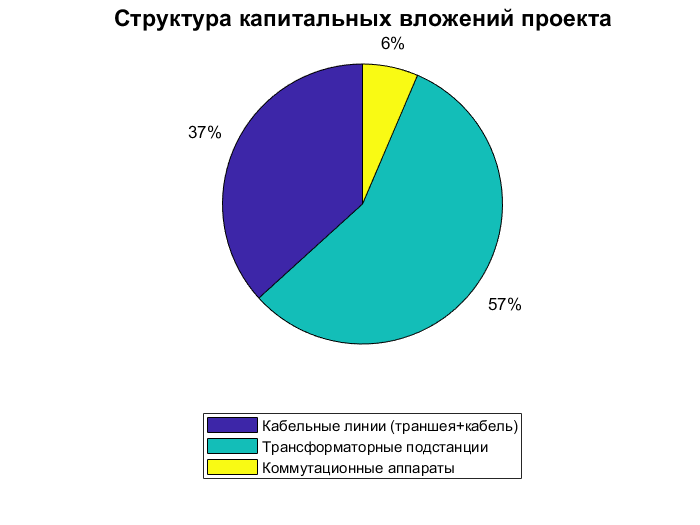


%% 4. Визуализация бюджета проекта
figure('Name', 'Структура капитальных вложений', 'Color', 'w');
% Данные для круговой диаграммы
Expenses = [K_KL_Total, K_KTP, K_Vyklyuchateli];
Labels = {'Кабельные линии (траншея+кабель)', 'Трансформаторные подстанции', 'Коммутационные аппараты'};

% Функция pie создает круговую диаграмму. Настройка отображения процентов.
p = pie(Expenses);
title('Структура капитальных вложений проекта', 'FontSize', 14);
legend(Labels, 'Location', 'southoutside');